# PART5 Trajectory generation and control

## Exercise 5.1: quintic splines

syms a_0 a_1 a_2 a_3 a_4 a_5
syms t t_1 t_0

eqn = a_0 + a_1 * t + a_2 *t^2 + a_3 *t^3 +a_4*t^4 +a_5*t^5

$$eqn = a_{5}\,t^{5}+a_{4}\,t^{4}+a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

solve(eqn==0, a_0)

$$ans = -a_{5}\,t^{5}-a_{4}\,t^{4}-a_{3}\,t^{3}-a_{2}\,t^{2}-a_{1}\,t$$

% x_0 = subs(eqn,t,0)
% x_1dot_0 = subs(diff(eqn,1),t,0)
% x_2dot_0 = subs(diff(eqn,2),t,0)
% 
% x_1 = subs(eqn,t,1)
% x_1dot_1 = subs(diff(eqn,1),t,1)
% x_2dot_1 = subs(diff(eqn,2),t,1)

x_0 = eqn

$$x\_0 = a_{5}\,t^{5}+a_{4}\,t^{4}+a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

x_1dot_0 = diff(eqn,1)

$$x\_1dot\_0 = 5\,a_{5}\,t^{4}+4\,a_{4}\,t^{3}+3\,a_{3}\,t^{2}+2\,a_{2}\,t+a_{1}$$

x_2dot_0 = diff(eqn,2)

$$x\_2dot\_0 = 20\,a_{5}\,t^{3}+12\,a_{4}\,t^{2}+6\,a_{3}\,t+2\,a_{2}$$


x_1 = eqn

$$x\_1 = a_{5}\,t^{5}+a_{4}\,t^{4}+a_{3}\,t^{3}+a_{2}\,t^{2}+a_{1}\,t+a_{0}$$

x_1dot_1 = subs(diff(eqn,1),t,t_1)

$$x\_1dot\_1 = 5\,a_{5}\,{t_{1}}^{4}+4\,a_{4}\,{t_{1}}^{3}+3\,a_{3}\,{t_{1}}^{2}+2\,a_{2}\,t_{1}+a_{1}$$

x_2dot_1 = subs(diff(eqn,2),t,t_1)

$$x\_2dot\_1 = 20\,a_{5}\,{t_{1}}^{3}+12\,a_{4}\,{t_{1}}^{2}+6\,a_{3}\,t_{1}+2\,a_{2}$$


t_0 = 0;
t_1 =1;
T = [   1, t_0, t_0^2, t_0^3, t_0^4, t_0^5;
        0, 1,   2*t_0, 3*t_0^2, 4*t_0^3, 5*t_0^4;
        0,  0,  2,     6*t_0,   12*t_0^2, 20*t_0^3;
        1, t_1, t_1^2, t_1^3, t_1^4, t_1^5;
        0, 1,   2*t_1, 3*t_1^2, 4*t_1^3, 5*t_1^4;
        0,  0,  2,     6*t_1,   12*t_1^2, 20*t_1^3;]

T =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     2     0     0     0
     1     1     1     1     1     1
     0     1     2     3     4     5
     0     0     2     6    12    20


b = [0,0,0,1,0,0]';
a = T\b

a =          0
         0
         0
   10.0000
  -15.0000
    6.0000


## Exercise 5.2: B-splines

Cox-de Boor recusion formula

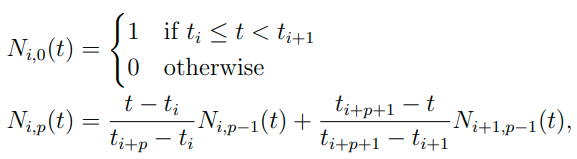

Compute the two first order basis functions N0,1(t) and N1,1(t) with ti = i and combine them linearly to interpolate between the two points (1, 2) and (2, 3).